clear all 
close all
clc
k = 0:0.1:pi;
km_1=((-8*cos(k)/3)+(cos(2*k)/6)+(5/2));%4th order
km_2=2-2*cos(k);%2nd order;


figure
plot(k.^2,km_1,'-r','linewidth',1.5)
hold on 
plot(k.^2,km_2,'-b','linewidth',1.5)
hold on
plot(k.^2,k.^2,'-k','linewidth',1.5)
xlabel('(k*delx)^2')
ylabel('(km*delx)^2')
legend('4th order','2nd order')

%Same code has been used for M= 30
clear all
clc
M=10;
dx=2*pi/M  

dx = 0.6283

m=(1:M);
j=(1:M);
 
 
for p=1:length(m)
    row1(p)=exp(1i*m(p)*dx);    
end
b=row1;
for q=2:length(j)
    b(q,:)=b(1,:).^(j(q));
end 
a=b

a =    0.8090 + 0.5878i   0.3090 + 0.9511i  -0.3090 + 0.9511i  -0.8090 + 0.5878i  -1.0000 + 0.0000i  -0.8090 - 0.5878i  -0.3090 - 0.9511i   0.3090 - 0.9511i   0.8090 - 0.5878i   1.0000 - 0.0000i
   0.3090 + 0.9511i  -0.8090 + 0.5878i  -0.8090 - 0.5878i   0.3090 - 0.9511i   1.0000 - 0.0000i   0.3090 + 0.9511i  -0.8090 + 0.5878i  -0.8090 - 0.5878i   0.3090 - 0.9511i   1.0000 - 0.0000i
  -0.3090 + 0.9511i  -0.8090 - 0.5878i   0.8090 - 0.5878i   0.3090 + 0.9511i  -1.0000 + 0.0000i   0.3090 - 0.9511i   0.8090 + 0.5878i  -0.8090 + 0.5878i  -0.3090 - 0.9511i   1.0000 - 0.0000i
  -0.8090 + 0.5878i   0.3090 - 0.9511i   0.3090 + 0.9511i  -0.8090 - 0.5878i   1.0000 - 0.0000i  -0.8090 + 0.5878i   0.3090 - 0.9511i   0.3090 + 0.9511i  -0.8090 - 0.5878i   1.0000 - 0.0000i
  -1.0000 + 0.0000i   1.0000 - 0.0000i  -1.0000 + 0.0000i   1.0000 - 0.0000i  -1.0000 + 0.0000i   1.0000 - 0.0000i  -1.0000 + 0.0000i   1.0000 - 0.0000i  -1.0000 + 0.0000i   1.0000 - 0.0000i
  -0.8090 - 0.5878i   0.3090 + 0.9511i   



% first assumption u(x,0) = sin(x)
for h=1:length(j)
    hrow(h,:)=(sin(j(h)*dx));
end
c=hrow;    %%% sin(x)
 
fm=(inv(a)*c)  % f(m) A = B/2X 

fm =    0.0000 - 0.5000i
  -0.0000 - 0.0000i
  -0.0000 + 0.0000i
  -0.0000 - 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.5000i
   0.0000 - 0.0000i




%% u(x,0) = sin (2x)
for h2 = 1:length(m)
    h2row(h2,:)= sin(2*(j(h2)*dx))
end

h2row = 0.9511

h2row =     0.9511
    0.5878


h2row =     0.9511
    0.5878
   -0.5878


h2row =     0.9511
    0.5878
   -0.5878
   -0.9511


h2row =     0.9511
    0.5878
   -0.5878
   -0.9511
   -0.0000


h2row =     0.9511
    0.5878
   -0.5878
   -0.9511
   -0.0000
    0.9511


h2row =     0.9511
    0.5878
   -0.5878
   -0.9511
   -0.0000
    0.9511
    0.5878


h2row =     0.9511
    0.5878
   -0.5878
   -0.9511
   -0.0000
    0.9511
    0.5878
   -0.5878


h2row =     0.9511
    0.5878
   -0.5878
   -0.9511
   -0.0000
    0.9511
    0.5878
   -0.5878
   -0.9511


h2row =     0.9511
    0.5878
   -0.5878
   -0.9511
   -0.0000
    0.9511
    0.5878
   -0.5878
   -0.9511
   -0.0000


g = h2row;  %% sin(2x)


% to solve for ODE,
% t = 2*pi
for p1 = 1:length(m)
    brow1(p1) = exp(1i*m(p1)*dx); % t = 0 to 2*pi
end
b1 = brow1;
for q1 = 2:length(j)
    b1(q1,:) = b1(1,:).^(j(q1))
end

b1 =    0.8090 + 0.5878i   0.3090 + 0.9511i  -0.3090 + 0.9511i  -0.8090 + 0.5878i  -1.0000 + 0.0000i  -0.8090 - 0.5878i  -0.3090 - 0.9511i   0.3090 - 0.9511i   0.8090 - 0.5878i   1.0000 - 0.0000i
   0.3090 + 0.9511i  -0.8090 + 0.5878i  -0.8090 - 0.5878i   0.3090 - 0.9511i   1.0000 - 0.0000i   0.3090 + 0.9511i  -0.8090 + 0.5878i  -0.8090 - 0.5878i   0.3090 - 0.9511i   1.0000 - 0.0000i


b1 =    0.8090 + 0.5878i   0.3090 + 0.9511i  -0.3090 + 0.9511i  -0.8090 + 0.5878i  -1.0000 + 0.0000i  -0.8090 - 0.5878i  -0.3090 - 0.9511i   0.3090 - 0.9511i   0.8090 - 0.5878i   1.0000 - 0.0000i
   0.3090 + 0.9511i  -0.8090 + 0.5878i  -0.8090 - 0.5878i   0.3090 - 0.9511i   1.0000 - 0.0000i   0.3090 + 0.9511i  -0.8090 + 0.5878i  -0.8090 - 0.5878i   0.3090 - 0.9511i   1.0000 - 0.0000i
  -0.3090 + 0.9511i  -0.8090 - 0.5878i   0.8090 - 0.5878i   0.3090 + 0.9511i  -1.0000 + 0.0000i   0.3090 - 0.9511i   0.8090 + 0.5878i  -0.8090 + 0.5878i  -0.3090 - 0.9511i   1.0000 - 0.0000i


b1 =    0.8090 + 0.5878i   0.3090 + 0.9511i  -0.3090 + 0.9511i  -0.8090 + 0.5878i  -1.0000 + 0.0000i  -0.8090 - 0.5878i  -0.3090 - 0.9511i   0.3090 - 0.9511i   0.8090 - 0.5878i   1.0000 - 0.0000i
   0.3090 + 0.9511i  -0.8090 + 0.5878i  -0.8090 - 0.5878i   0.3090 - 0.9511i   1.0000 - 0.0000i   0.3090 + 0.9511i  -0.8090 + 0.5878i  -0.8090 - 0.5878i   0.3090 - 0.9511i   1.0000 - 0.0000i
  -0.3090 + 0.9511i  -0.8090 - 0.5878i   0.8090 - 0.5878i   0.3090 + 0.9511i  -1.0000 + 0.0000i   0.3090 - 0.9511i   0.8090 + 0.5878i  -0.8090 + 0.5878i  -0.3090 - 0.9511i   1.0000 - 0.0000i
  -0.8090 + 0.5878i   0.3090 - 0.9511i   0.3090 + 0.9511i  -0.8090 - 0.5878i   1.0000 - 0.0000i  -0.8090 + 0.5878i   0.3090 - 0.9511i   0.3090 + 0.9511i  -0.8090 - 0.5878i   1.0000 - 0.0000i


b1 =    0.8090 + 0.5878i   0.3090 + 0.9511i  -0.3090 + 0.9511i  -0.8090 + 0.5878i  -1.0000 + 0.0000i  -0.8090 - 0.5878i  -0.3090 - 0.9511i   0.3090 - 0.9511i   0.8090 - 0.5878i   1.0000 - 0.0000i
   0.3090 + 0.9511i  -0.8090 + 0.5878i  -0.8090 - 0.5878i   0.3090 - 0.9511i   1.0000 - 0.0000i   0.3090 + 0.9511i  -0.8090 + 0.5878i  -0.8090 - 0.5878i   0.3090 - 0.9511i   1.0000 - 0.0000i
  -0.3090 + 0.9511i  -0.8090 - 0.5878i   0.8090 - 0.5878i   0.3090 + 0.9511i  -1.0000 + 0.0000i   0.3090 - 0.9511i   0.8090 + 0.5878i  -0.8090 + 0.5878i  -0.3090 - 0.9511i   1.0000 - 0.0000i
  -0.8090 + 0.5878i   0.3090 - 0.9511i   0.3090 + 0.9511i  -0.8090 - 0.5878i   1.0000 - 0.0000i  -0.8090 + 0.5878i   0.3090 - 0.9511i   0.3090 + 0.9511i  -0.8090 - 0.5878i   1.0000 - 0.0000i
  -1.0000 + 0.0000i   1.0000 - 0.0000i  -1.0000 + 0.0000i   1.0000 - 0.0000i  -1.0000 + 0.0000i   1.0000 - 0.0000i  -1.0000 + 0.0000i   1.0000 - 0.0000i  -1.0000 + 0.0000i   1.0000 - 0.0000i


b1 =    0.8090 + 0.5878i   0.3090 + 0.9511i  -0.3090 + 0.9511i  -0.8090 + 0.5878i  -1.0000 + 0.0000i  -0.8090 - 0.5878i  -0.3090 - 0.9511i   0.3090 - 0.9511i   0.8090 - 0.5878i   1.0000 - 0.0000i
   0.3090 + 0.9511i  -0.8090 + 0.5878i  -0.8090 - 0.5878i   0.3090 - 0.9511i   1.0000 - 0.0000i   0.3090 + 0.9511i  -0.8090 + 0.5878i  -0.8090 - 0.5878i   0.3090 - 0.9511i   1.0000 - 0.0000i
  -0.3090 + 0.9511i  -0.8090 - 0.5878i   0.8090 - 0.5878i   0.3090 + 0.9511i  -1.0000 + 0.0000i   0.3090 - 0.9511i   0.8090 + 0.5878i  -0.8090 + 0.5878i  -0.3090 - 0.9511i   1.0000 - 0.0000i
  -0.8090 + 0.5878i   0.3090 - 0.9511i   0.3090 + 0.9511i  -0.8090 - 0.5878i   1.0000 - 0.0000i  -0.8090 + 0.5878i   0.3090 - 0.9511i   0.3090 + 0.9511i  -0.8090 - 0.5878i   1.0000 - 0.0000i
  -1.0000 + 0.0000i   1.0000 - 0.0000i  -1.0000 + 0.0000i   1.0000 - 0.0000i  -1.0000 + 0.0000i   1.0000 - 0.0000i  -1.0000 + 0.0000i   1.0000 - 0.0000i  -1.0000 + 0.0000i   1.0000 - 0.0000i
  -0.8090 - 0.5878i   0.3090 + 0.9511i  

b1 =    0.8090 + 0.5878i   0.3090 + 0.9511i  -0.3090 + 0.9511i  -0.8090 + 0.5878i  -1.0000 + 0.0000i  -0.8090 - 0.5878i  -0.3090 - 0.9511i   0.3090 - 0.9511i   0.8090 - 0.5878i   1.0000 - 0.0000i
   0.3090 + 0.9511i  -0.8090 + 0.5878i  -0.8090 - 0.5878i   0.3090 - 0.9511i   1.0000 - 0.0000i   0.3090 + 0.9511i  -0.8090 + 0.5878i  -0.8090 - 0.5878i   0.3090 - 0.9511i   1.0000 - 0.0000i
  -0.3090 + 0.9511i  -0.8090 - 0.5878i   0.8090 - 0.5878i   0.3090 + 0.9511i  -1.0000 + 0.0000i   0.3090 - 0.9511i   0.8090 + 0.5878i  -0.8090 + 0.5878i  -0.3090 - 0.9511i   1.0000 - 0.0000i
  -0.8090 + 0.5878i   0.3090 - 0.9511i   0.3090 + 0.9511i  -0.8090 - 0.5878i   1.0000 - 0.0000i  -0.8090 + 0.5878i   0.3090 - 0.9511i   0.3090 + 0.9511i  -0.8090 - 0.5878i   1.0000 - 0.0000i
  -1.0000 + 0.0000i   1.0000 - 0.0000i  -1.0000 + 0.0000i   1.0000 - 0.0000i  -1.0000 + 0.0000i   1.0000 - 0.0000i  -1.0000 + 0.0000i   1.0000 - 0.0000i  -1.0000 + 0.0000i   1.0000 - 0.0000i
  -0.8090 - 0.5878i   0.3090 + 0.9511i  

b1 =    0.8090 + 0.5878i   0.3090 + 0.9511i  -0.3090 + 0.9511i  -0.8090 + 0.5878i  -1.0000 + 0.0000i  -0.8090 - 0.5878i  -0.3090 - 0.9511i   0.3090 - 0.9511i   0.8090 - 0.5878i   1.0000 - 0.0000i
   0.3090 + 0.9511i  -0.8090 + 0.5878i  -0.8090 - 0.5878i   0.3090 - 0.9511i   1.0000 - 0.0000i   0.3090 + 0.9511i  -0.8090 + 0.5878i  -0.8090 - 0.5878i   0.3090 - 0.9511i   1.0000 - 0.0000i
  -0.3090 + 0.9511i  -0.8090 - 0.5878i   0.8090 - 0.5878i   0.3090 + 0.9511i  -1.0000 + 0.0000i   0.3090 - 0.9511i   0.8090 + 0.5878i  -0.8090 + 0.5878i  -0.3090 - 0.9511i   1.0000 - 0.0000i
  -0.8090 + 0.5878i   0.3090 - 0.9511i   0.3090 + 0.9511i  -0.8090 - 0.5878i   1.0000 - 0.0000i  -0.8090 + 0.5878i   0.3090 - 0.9511i   0.3090 + 0.9511i  -0.8090 - 0.5878i   1.0000 - 0.0000i
  -1.0000 + 0.0000i   1.0000 - 0.0000i  -1.0000 + 0.0000i   1.0000 - 0.0000i  -1.0000 + 0.0000i   1.0000 - 0.0000i  -1.0000 + 0.0000i   1.0000 - 0.0000i  -1.0000 + 0.0000i   1.0000 - 0.0000i
  -0.8090 - 0.5878i   0.3090 + 0.9511i  

b1 =    0.8090 + 0.5878i   0.3090 + 0.9511i  -0.3090 + 0.9511i  -0.8090 + 0.5878i  -1.0000 + 0.0000i  -0.8090 - 0.5878i  -0.3090 - 0.9511i   0.3090 - 0.9511i   0.8090 - 0.5878i   1.0000 - 0.0000i
   0.3090 + 0.9511i  -0.8090 + 0.5878i  -0.8090 - 0.5878i   0.3090 - 0.9511i   1.0000 - 0.0000i   0.3090 + 0.9511i  -0.8090 + 0.5878i  -0.8090 - 0.5878i   0.3090 - 0.9511i   1.0000 - 0.0000i
  -0.3090 + 0.9511i  -0.8090 - 0.5878i   0.8090 - 0.5878i   0.3090 + 0.9511i  -1.0000 + 0.0000i   0.3090 - 0.9511i   0.8090 + 0.5878i  -0.8090 + 0.5878i  -0.3090 - 0.9511i   1.0000 - 0.0000i
  -0.8090 + 0.5878i   0.3090 - 0.9511i   0.3090 + 0.9511i  -0.8090 - 0.5878i   1.0000 - 0.0000i  -0.8090 + 0.5878i   0.3090 - 0.9511i   0.3090 + 0.9511i  -0.8090 - 0.5878i   1.0000 - 0.0000i
  -1.0000 + 0.0000i   1.0000 - 0.0000i  -1.0000 + 0.0000i   1.0000 - 0.0000i  -1.0000 + 0.0000i   1.0000 - 0.0000i  -1.0000 + 0.0000i   1.0000 - 0.0000i  -1.0000 + 0.0000i   1.0000 - 0.0000i
  -0.8090 - 0.5878i   0.3090 + 0.9511i  

b1 =    0.8090 + 0.5878i   0.3090 + 0.9511i  -0.3090 + 0.9511i  -0.8090 + 0.5878i  -1.0000 + 0.0000i  -0.8090 - 0.5878i  -0.3090 - 0.9511i   0.3090 - 0.9511i   0.8090 - 0.5878i   1.0000 - 0.0000i
   0.3090 + 0.9511i  -0.8090 + 0.5878i  -0.8090 - 0.5878i   0.3090 - 0.9511i   1.0000 - 0.0000i   0.3090 + 0.9511i  -0.8090 + 0.5878i  -0.8090 - 0.5878i   0.3090 - 0.9511i   1.0000 - 0.0000i
  -0.3090 + 0.9511i  -0.8090 - 0.5878i   0.8090 - 0.5878i   0.3090 + 0.9511i  -1.0000 + 0.0000i   0.3090 - 0.9511i   0.8090 + 0.5878i  -0.8090 + 0.5878i  -0.3090 - 0.9511i   1.0000 - 0.0000i
  -0.8090 + 0.5878i   0.3090 - 0.9511i   0.3090 + 0.9511i  -0.8090 - 0.5878i   1.0000 - 0.0000i  -0.8090 + 0.5878i   0.3090 - 0.9511i   0.3090 + 0.9511i  -0.8090 - 0.5878i   1.0000 - 0.0000i
  -1.0000 + 0.0000i   1.0000 - 0.0000i  -1.0000 + 0.0000i   1.0000 - 0.0000i  -1.0000 + 0.0000i   1.0000 - 0.0000i  -1.0000 + 0.0000i   1.0000 - 0.0000i  -1.0000 + 0.0000i   1.0000 - 0.0000i
  -0.8090 - 0.5878i   0.3090 + 0.9511i  

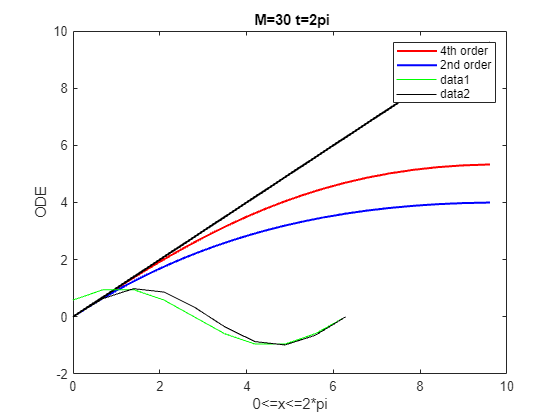

a1=b1;
fm2=(inv(a1)*g); % sin2x


odesin = a*fm;
odesin2 = a1*fm2;
z = linspace(0,2*pi,M); % x for  0 to 2pi


% figure
% plot(z,ode)
%Multiplying the above matrix with fm gives the ODE solution
%z=linspace(dx,2*pi,M); % 0<=x<=2*pi
pde=sin(z);
figure (1)
plot(z,real(odesin),'g',z,pde,'black')
title(' M=30 t=2pi')
xlabel('0<=x<=2*pi')
ylabel('ODE')

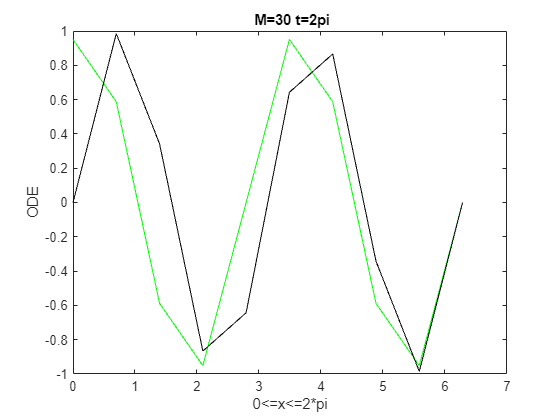



pde2=sin(2*z);
figure (2)
plot(z,real(odesin2),'g',z,pde2,'black')
title(' M=30 t=2pi')
xlabel('0<=x<=2*pi')
ylabel('ODE')